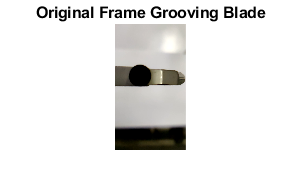

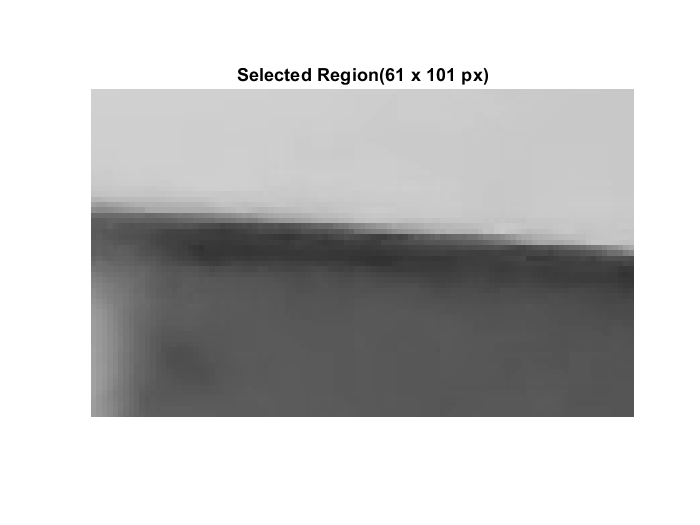

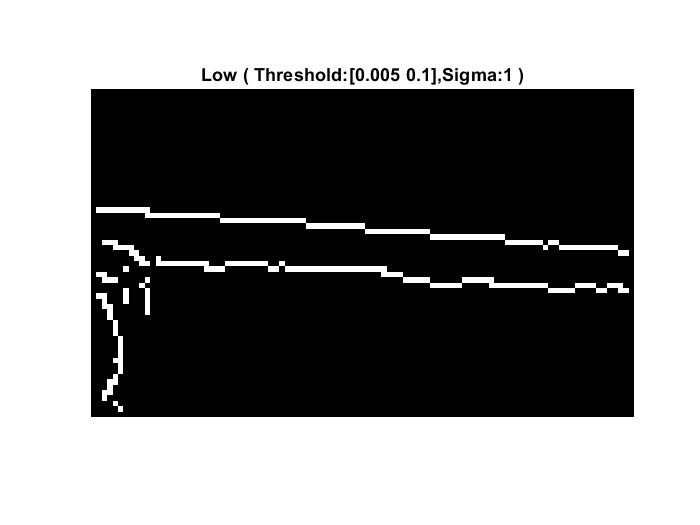

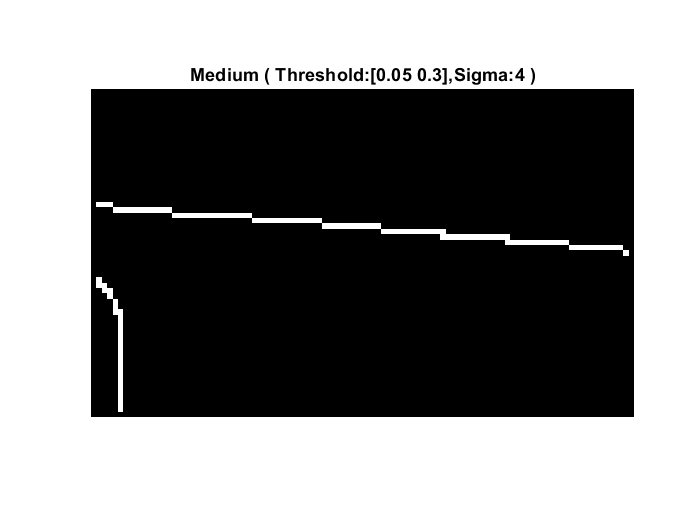

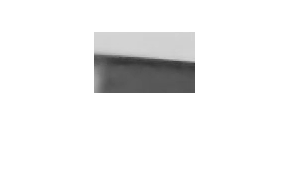

clear;
v=VideoReader("C:\Users\Varun\Desktop\Lab\DataSet\Grooving.mp4"); % Reading Video
disp1=[];
disp2=[];
disp3=[];
i=1;
x=0;
y=0;
for nFrames = 454:900    
    % Acquire single frame
    frameRGB = read(v,nFrames);
    I2 = rgb2gray(imcrop(frameRGB,[480 440 100 60]));
    imshow(I2)
    frameRGB1=edge(I2,'canny',[0.005 0.1],1); % Threshold 1
    [y,x]=find(frameRGB);
    x1=mean(x)*37.5e-03;
    y1=mean(y)*37.5e-03;
    disp1(i)=y1;
    
    frameRGB2=edge(I2,'canny',[0.05 0.3],4); % Threshold 2
    [y,x]=find(frameRGB2);
    x2=mean(x)*37.5e-03;
    y2=mean(y)*37.5e-03;
    disp2(i)=y2;
    
    frameRGB3=edge(I2,'canny',[0.3 0.8],8); % Threshold 3
    [y,x]=find(frameRGB3);
    x3=mean(x)*37.5e-03;
    y3=mean(y)*37.5e-03;
    disp3(i)=y3;
    
    if nFrames==454
      % Displaying Region Selection and detected edge
      imshow(frameRGB,'InitialMagnification','fit')
      title('Original Frame Grooving Blade')
      figure,imshow(I2,'InitialMagnification','fit')
      title('Selected Region(61 x 101 px)')
      figure,imshow(frameRGB1,'InitialMagnification','fit')
      title('Low ( Threshold:[0.005 0.1],Sigma:1 )')
      figure,imshow(frameRGB2,'InitialMagnification','fit')
      title('Medium ( Threshold:[0.05 0.3],Sigma:4 )')
      figure,imshow(frameRGB3,'InitialMagnification','fit')
      title('High ( Threshold:[0.3 0.8],Sigma:8 )')
    end
    
    i=i+1;
end

disp1=disp1-disp1(1); % Removing Offset
disp2=disp2-disp2(1);
disp3=disp3-disp3(1);
time=(0:446)./480;

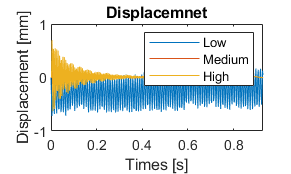

plot(time,disp1)
hold on
plot(time,disp2)
plot(time,disp3)
title('Displacemnet')
legend('Low','Medium','High')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
% ylim([-0.12 0.12])
hold off

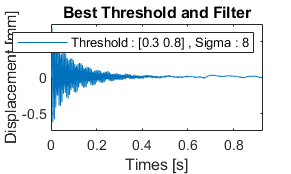

plot(time,disp3)
title('Best Threshold and Filter')
legend('Threshold : [0.3 0.8] , Sigma : 8')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
ylim([-0.75 0.75])

% Lenght of signal
L = length(time);
% Sampling Freq
dt = time(2) - time(1);
Fs = 1/dt;
% Define a freq. vector
f = Fs/2*linspace(0,1,(L/2+1)); % in Hz
w = (f*2*pi)'; % in rad/sec
F=fft(disp3,L); %FFT
F=F(1:length(F)/2+1);

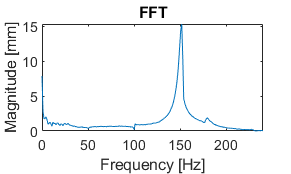

plot(f,abs(F))
title('FFT')
xlabel('Frequency [Hz]')
ylabel('Magnitude [mm]')
xlim([0 f(end)])

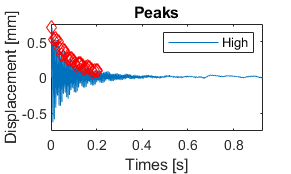

[ypk,xpk] = findpeaks(disp3(1:100));
plot(time,disp3,time(xpk),ypk,'dr');
title('Peaks')
legend('High')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
ylim([-0.75 0.75])

np=numel(xpk);


tn = time(xpk);    
% Calculating Logarithmic Decrement
Log_Dec = zeros(length(np));  
for i = 1:np-1 
    Log_Dec(i)= log(ypk(i)/ypk(i+1));
end  
lambda = mean(Log_Dec); %Calculating Average Logarithmic Decrement

z1=lambda/sqrt(lambda^2 + 4*pi^2)  %Zeta

z1 = 0.0103

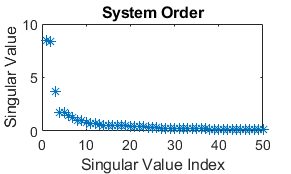

% ERA
H0=hankel(disp3); % First Hankel Matrix
[U,S,V]=svd(H0); %SVD decomposition
S=diag(S); 
plot(S,'*')
title('System Order')
xlabel('Singular Value Index')
ylabel('Singular Value')
xlim([0 time(end)])
xlim([0 50])

cut=2;
S1=diag(sqrt(S(1:cut)));
Sinv=inv(S1);
U1=U(:,1:cut);               
V1=V(:,1:cut);

H1=[];
for i=2:size(H0,1)
  H1(i-1,:)=H0(i,:);
end
H1(i,:)=zeros(1,size(H1,2));% Second Hankel Matrix

Ad=Sinv*U1'*H1*V1*Sinv;
Bd=S1*V1';
Bd=Bd(:,1);            
Cd=U1*S1;
Cd=Cd(1,:);            
[ep,ev]=eig(Ad);
ev=diag(ev);

dt=time(2)-time(1);
phi=Cd*ep

phi =    0.4105 - 0.3795i   0.4105 + 0.3795i


w=[];
z2=[];
for i=1:size(Ad,1)
  lambda=(1/dt)*(log(abs(ev(i))) + 1i*angle(ev(i))); 
  w(i)=abs(lambda); % Natural Frequency
  z2(i)=-real(lambda)/w(i); % Zeta
  fn(i)=w(i)/(2*pi);
end
w

w =   945.1604  945.1604


z2

z2 =     0.0097    0.0097


fn

fn =   150.4269  150.4269


soundsc(disp3)